# **Determination of total property damage in the seven states most affected by Hurricane Harvey between August 17th and September 3rd, 2017**

#### Step 1: 

#### Creating an import function y to import the "stormevents_2017_finalproject.csv" file which include CZ_Name variable

% importing stormevents_2017_finalproject.csv file into the live editor
y = importfile("stormevents_2017_finalproject.csv");

#### Step 2: 

#### Filtering the table to include only seven states: Arkansas, Kentucky, Louisiana, Mississippi, North Carolina, Tennessee, and Texas.

% filtering the table y to show data related to only seven states
y_seven_states = y(ismember(y.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);


#### Step 3: 

#### Filtering the table further to include only events that start between August 17th and September 3rd (both inclusive)

% Filter by date range (adjust column name as needed)
start_date = datetime('2017-08-17');
end_date = datetime('2017-09-03');

% Assuming the date column is called 'Begin_Date' - change if different
date_column = 'Begin_Date_Time'; % Adjust this based on your actual column name



% Filter for Hurricane Harvey period
harvey_mask = y_seven_states.(date_column) >= start_date & ...
              y_seven_states.(date_column) <= end_date;
y_harvey = y_seven_states(harvey_mask, :)

y_harvey = 578×24 table
    EpisodeID      Event_ID         State         Year      Month         Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                            

#### Step 4: 

#### Total property cost for each state to determine the states with the most damage

% Compute group summary
total_property_cost_by_state = groupsummary(y_harvey,"State","sum","Property_Cost");
total_property_cost_by_state = sortrows(total_property_cost_by_state, "sum_Property_Cost", "descend")

total_property_cost_by_state = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                275           7.7427e+10    
    LOUISIANA             86           7.5277e+07    
    NORTH CAROLINA        59           1.2338e+07    
    MISSISSIPPI           39             9.15e+05    
    TENNESSEE             46             5.04e+05    
    KENTUCKY              20             4.35e+05    
    ARKANSAS              53                61000    



total_property_cost_by_state = sortrows(total_property_cost_by_state, "sum_Property_Cost", "descend")

total_property_cost_by_state = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                275           7.7427e+10    
    LOUISIANA             86           7.5277e+07    
    NORTH CAROLINA        59           1.2338e+07    
    MISSISSIPPI           39             9.15e+05    
    TENNESSEE             46             5.04e+05    
    KENTUCKY              20             4.35e+05    
    ARKANSAS              53                61000    


#### Step 5:

#### Total property cost for each unique county to determine the regions within the states most impacted


total_property_cost_by_county = groupsummary(y_harvey, {'State', 'CZ_Name'}, 'sum', 'Property_Cost');
total_property_cost_by_county = sortrows(total_property_cost_by_county, 'sum_Property_Cost', 'descend')

total_property_cost_by_county = 241×4 table
    State      CZ_Name       GroupCount    sum_Property_Cost
    _____    ____________    __________    _________________

    TEXAS    GALVESTON           17                2e+10    
    TEXAS    FORT BEND           13           1.6004e+10    
    TEXAS    MONTGOMERY           6              1.4e+10    
    TEXAS    HARRIS              21           1.0001e+10    
    TEXAS    JEFFERSON            5                3e+09    
    TEXAS    BRAZORIA            12           2.0008e+09    
    TEXAS    ARANSAS              2             1.95e+09    
    TEXAS    ORANGE               3              1.5e+09    
    TEXAS    NUECES               2              1.3e+09    
    TEXAS    WALKER               4              1.2e+09    
    TEXAS    LIBERTY              4                1e+09    
    TEXAS    SAN JACINTO  

#### Step 6:

#### Total number of recorded events in each county, regardless of the amount of property cost


events_by_county = groupsummary(y_harvey, {'State', 'CZ_Name', 'Event_Type'});

events_by_county = sortrows(events_by_county, "GroupCount", "descend")

events_by_county = 360×4 table
        State           CZ_Name          Event_Type        GroupCount
    ______________    ____________    _________________    __________

    LOUISIANA         NATCHITOCHES    Flash Flood              19    
    TEXAS             HARRIS          Flash Flood              14    
    LOUISIANA         SABINE          Flash Flood              13    
    TEXAS             GALVESTON       Flash Flood              12    
    TEXAS             SABINE          Flash Flood              10    
    TEXAS             ANGELINA        Flash Flood               9    
    LOUISIANA         RED RIVER       Flash Flood               8    
    NORTH CAROLINA    GREENE          Flash Flood               7    
    TEXAS             BASTROP         Flash Flood               7    
    TEXAS             CHAMBERS        Flash Flood             

#### Step 7: 

#### The most common event types recorded throughout the storm



common_event_types = groupsummary(y_harvey,"Event_Type");

common_event_types = sortrows(common_event_types, "GroupCount", "descend")

common_event_types = 14×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood             241    
    Thunderstorm Wind        87    
    Heat                     55    
    Tornado                  51    
    Tropical Storm           44    
    Flood                    25    
    Hail                     20    
    Strong Wind              18    
    Heavy Rain               11    
    Storm Surge/Tide         10    
    Hurricane                 9    
    Funnel Cloud              3    
    Lightning                 3    
    High Wind                 1    


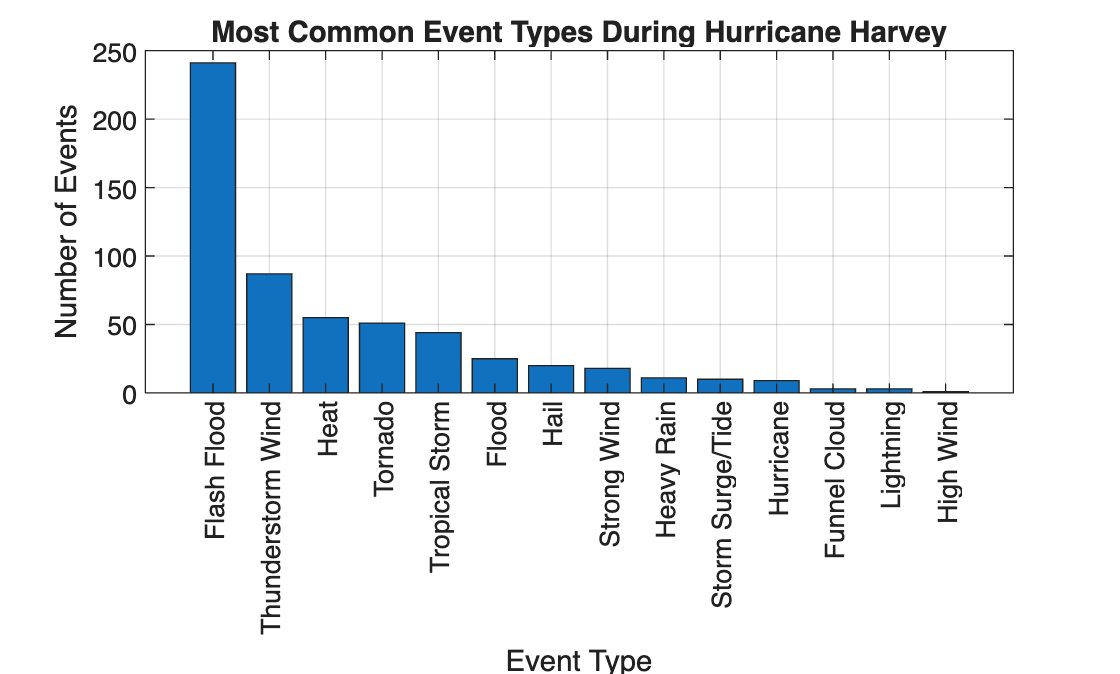

common_event_types = groupsummary(y_harvey, "Event_Type");
common_event_types = sortrows(common_event_types, "GroupCount", "descend");

% Bar chart
figure;
bar(common_event_types.GroupCount);
title('Most Common Event Types During Hurricane Harvey');
xlabel('Event Type');
ylabel('Number of Events');
xticklabels(common_event_types.Event_Type);
xtickangle(90); % Rotate labels for readability
grid on;